clc 
clear
m=6

m = 6

g=9.8

g = 9.8000

r=0.037

r = 0.0370

l=0.4

l = 0.4000

u=0.5

u = 0.5000

F1=0:10:200;%磁力为半边磁力
a=0.2

a = 0.2000

b=0.3

b = 0.3000

A=m.*g.*a.*(1+u.*u)+F1.*b.*(1+u.*u)+(u.*r-l).*(m.*g+F1)

A =    -7.7322   -7.7972   -7.8622   -7.9272   -7.9922   -8.0572   -8.1222   -8.1872   -8.2522   -8.3172   -8.3822   -8.4472   -8.5122   -8.5772   -8.6422   -8.7072   -8.7722   -8.8372   -8.9022   -8.9672   -9.0322


B=(u.*r-l).*(m.*g+F1).*(-u)

B =    11.2161   13.1236   15.0311   16.9386   18.8461   20.7536   22.6611   24.5686   26.4761   28.3836   30.2911   32.1986   34.1061   36.0136   37.9211   39.8286   41.7361   43.6436   45.5511   47.4586   49.3661


C=u.*r.*(u.*m.*g+F1.*u)

C =     0.5439    0.6364    0.7289    0.8214    0.9139    1.0064    1.0989    1.1914    1.2839    1.3764    1.4689    1.5614    1.6539    1.7464    1.8389    1.9314    2.0239    2.1164    2.2089    2.3014    2.3939


w=sqrt((B.*B-C.*C)./(A.*A+B.*B)+(A.*C./(A.*A+B.*B)).*(A.*C./(A.*A+B.*B)))-A.*C./(A.*A+B.*B)%w即为求的sinβ;问题出在w身上

w =     0.8453    0.8803    0.9052    0.9235    0.9371    0.9476    0.9558    0.9623    0.9675    0.9717    0.9752    0.9781    0.9806    0.9826    0.9844    0.9859    0.9873    0.9884    0.9894    0.9903    0.9911


h1=r.*(1-sqrt(1-w.*w)).*1000

h1 =    17.2324   19.4435   21.2756   22.8037   24.0896   25.1821   26.1191   26.9299   27.6372   28.2591   28.8095   29.2999   29.7393   30.1351   30.4934   30.8191   31.1164   31.3889   31.6395   31.8707   32.0846


disp(h1)

   17.2324   19.4435   21.2756   22.8037   24.0896   25.1821   26.1191   26.9299   27.6372   28.2591   28.8095   29.2999   29.7393   30.1351   30.4934   30.8191   31.1164   31.3889   31.6395   31.8707   32.0846



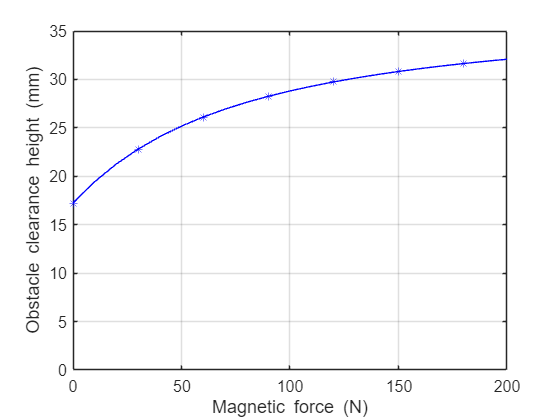

plot(F1,h1,'blue-*','MarkerIndices',1:3:length(h1))
set(gca,'XTick',0:50:200);
set(gca,'XTicklabel',{'0','50','100','150','200'})
set(gca,'YTicklabel',{'0','5','10','15','20','25','30','35'})
set(gca,'YTick',0:5:35);
axis([0 200 0 35])
set(gca,'FontSize',12)
grid on;
ylabel('Obstacle clearance height {\rm(mm)}')
xlabel('Magnetic force {\rm(N)}')

%ylabel('越障高度{\rm(mm)}')
%xlabel('磁力{\rm(N)}')